Generate a training dataset

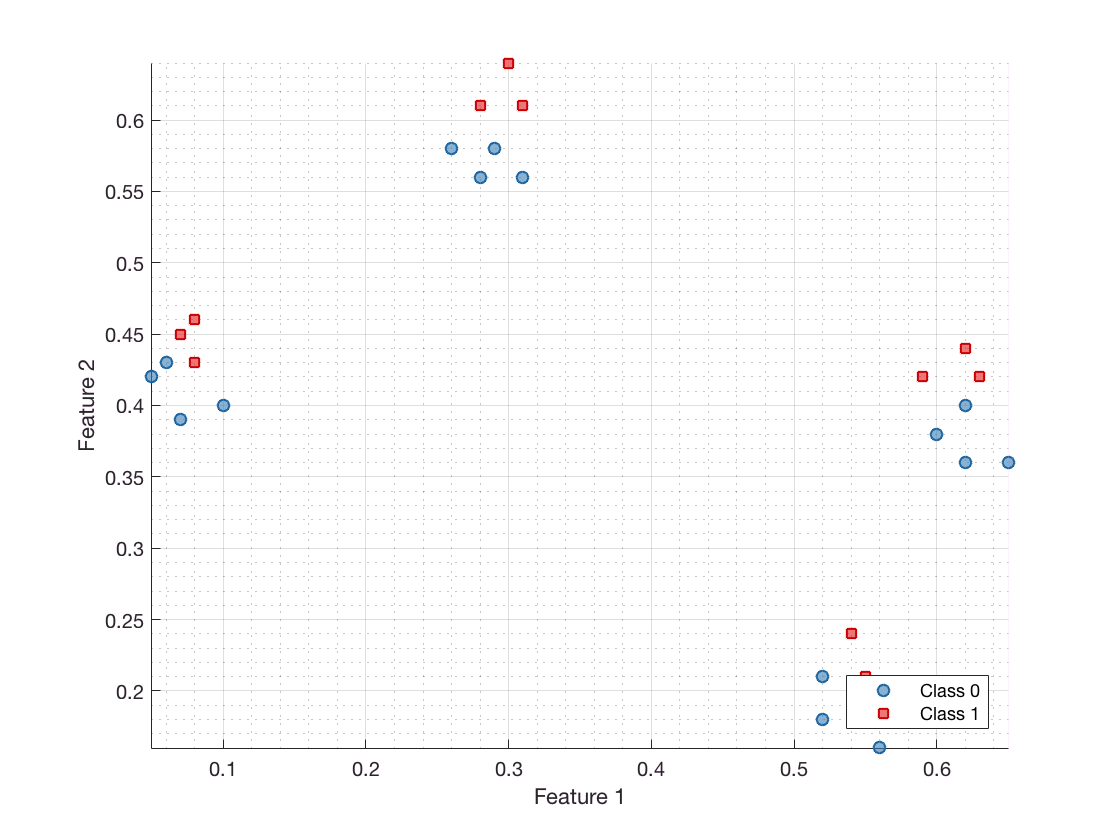

X = [0.05 0.42
0.06 0.43
0.07 0.39
0.10 0.40
0.07 0.45
0.08 0.46
0.08 0.43
0.26 0.58
0.29 0.58
0.28 0.56
0.31 0.56
0.28 0.61
0.30 0.64
0.31 0.61
0.52 0.18
0.52 0.21
0.55 0.20
0.56 0.16
0.54 0.24
0.55 0.21
0.57 0.20
0.60 0.38
0.62 0.40
0.62 0.36
0.65 0.36
0.59 0.42
0.62 0.44
0.63 0.42];
Y = [0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1]';
ds_train = prtDataSetClass(X,Y);
plot(ds_train)
axis equal tight

Generate a testing/validation dataset

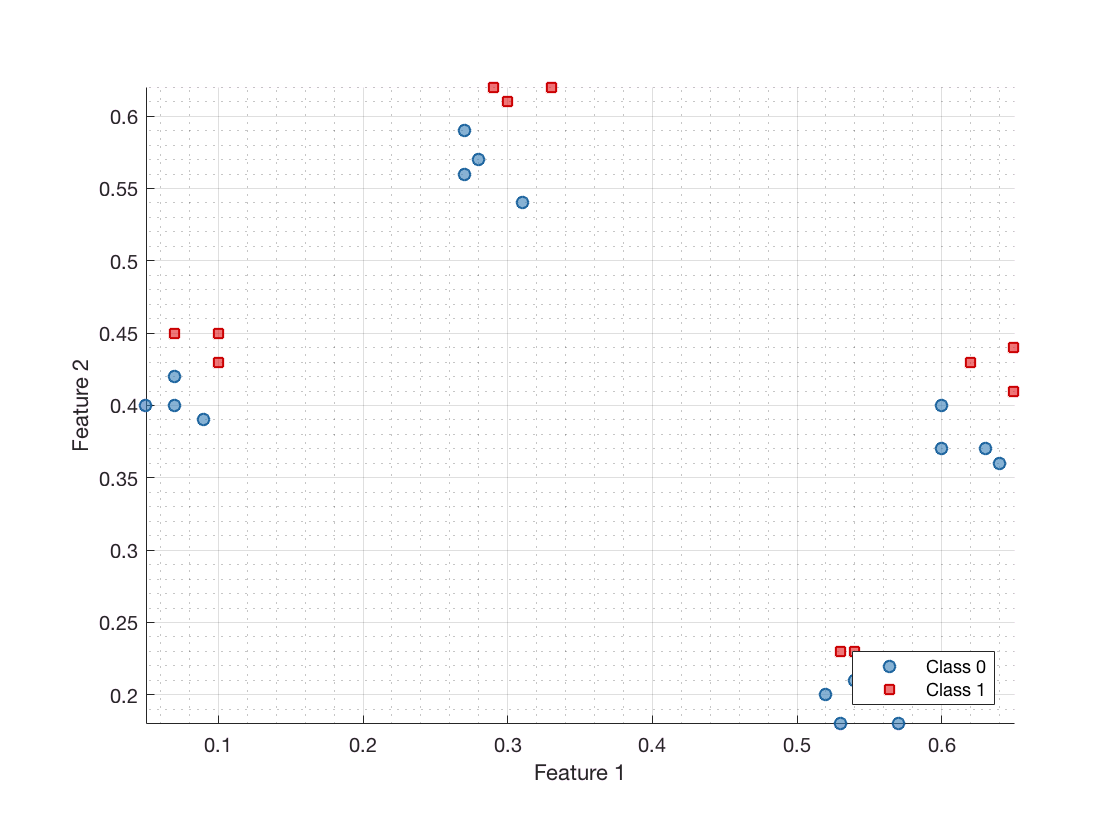

X = [0.05 0.40
0.07 0.42
0.09 0.39
0.07 0.40
0.10 0.45
0.07 0.45
0.10 0.43
0.27 0.59
0.27 0.56
0.28 0.57
0.31 0.54
0.30 0.61
0.29 0.62

0.33 0.62
0.60 0.40
0.63 0.37
0.60 0.37
0.64 0.36
0.65 0.41
0.65 0.44
0.62 0.43
0.52 0.20
0.53 0.18
0.54 0.21
0.57 0.18
0.53 0.23
0.54 0.23
0.57 0.22];
Y = [0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1]';
ds_test = prtDataSetClass(X,Y);
plot(ds_test)
axis equal tight

Build, train, and plot a KNN classifier

for i=1:7
    classifier = prtClassKnn('k',i);
    classifier = classifier+prtDecisionBinaryMinPe;
    classifier_trained = classifier.train(ds_train);
%     plot(classifier_trained.actionCell{1})
%     %title(["K-Nearest Neighbor, k=",num2str(i)])
%     axis equal tight
%     colorbar
    
    results = classifier_trained.run(ds_test);
    if i==1
        figure;
    end
    prtScoreRoc(results)
    prtScorePercentCorrect(results)
    title(["ROC Curve"])
    hold on;
    % the values associated with the classifier contour are the number
    % of nearest neighbors that are red (Class 1)
end

ans = 0.8929

ans = 0.8929

ans = 1

ans = 0.8929

ans = 0.8929

ans = 0.8571

ans = 0.5714

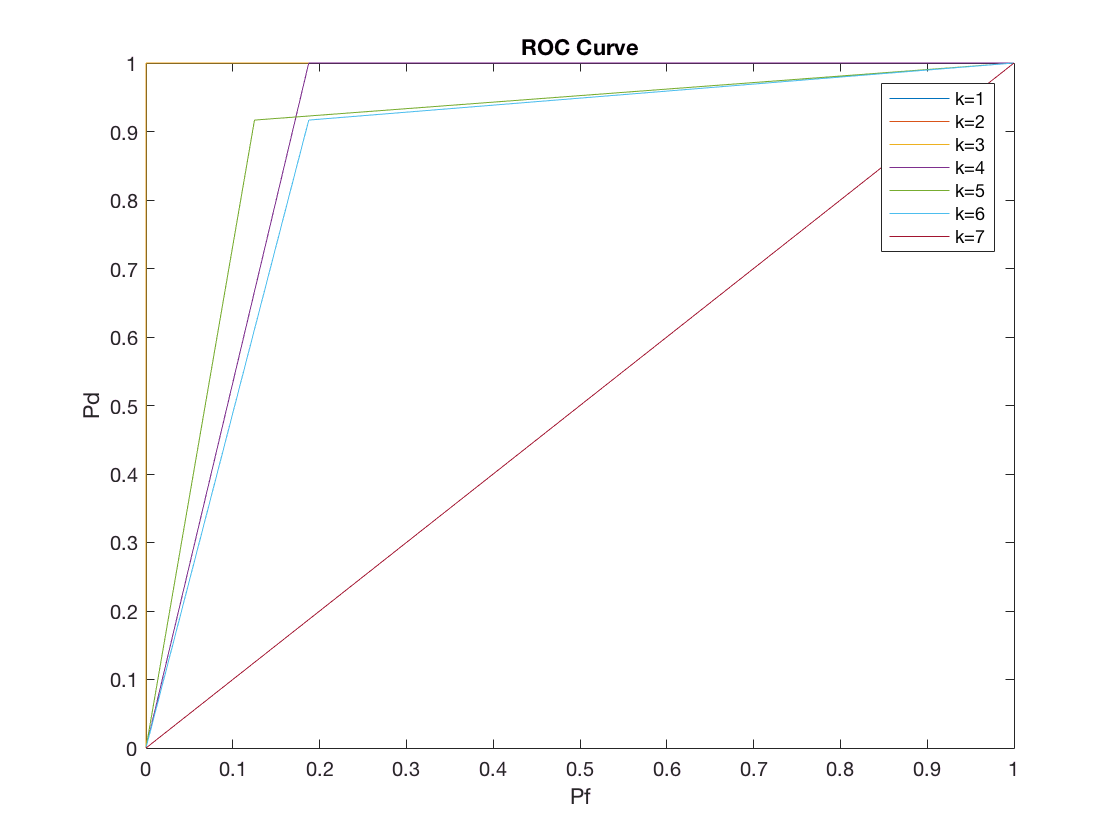

 legend('k=1','k=2','k=3','k=4','k=5','k=6','k=7');
  hold off;

a. For this dataset, it looks like k=3 is the best value. 

b. In general, a ROC curve for a good classifier looks a close as possible to a square box with a height and width of 1.  The point (0,1) indicates a perfect classifier.  (Has an area under the curve approaching 1. )

c. A poor classifier falls has a curve that behaves similarly to or falls below the line y=x. (Has an area under the curve <= 0.5) 